
load("PRNList.mat");
IF = 0;
fs = 10.23e6;
time_chip = 0.01;
Ts = 1/fs;
doppler_freq = 5e3;
freq_interval = 5e2;
N = 2

N = 2

% read data
fid = fopen('B1C_Signal_IQ_INT8.dat', 'r');
signal = fread(fid, 6*fs, 'int8');
signal = zeros(N, time_chip * 2 * fs);
for i = 1:N
    signal(i, :) = fread(fid, 2 * fs * time_chip, 'int8');
end

fclose(fid);

using fft to convolve

    20



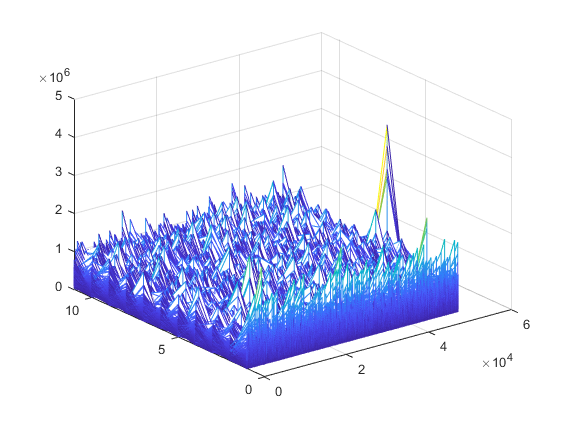

    21



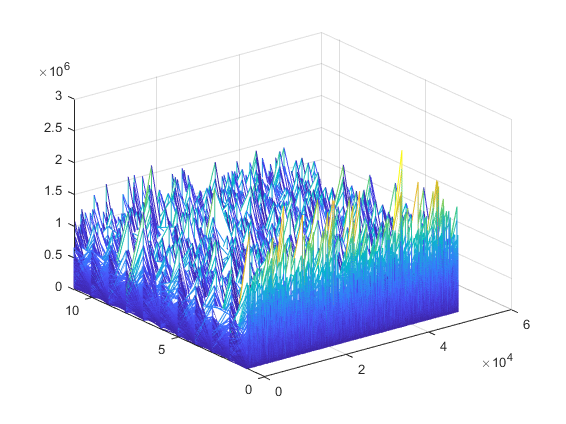

    22



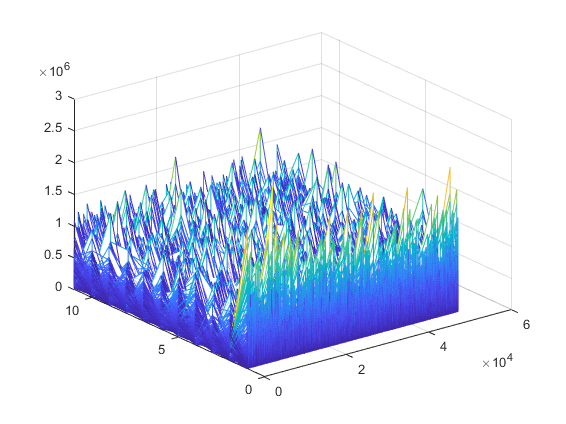

    23



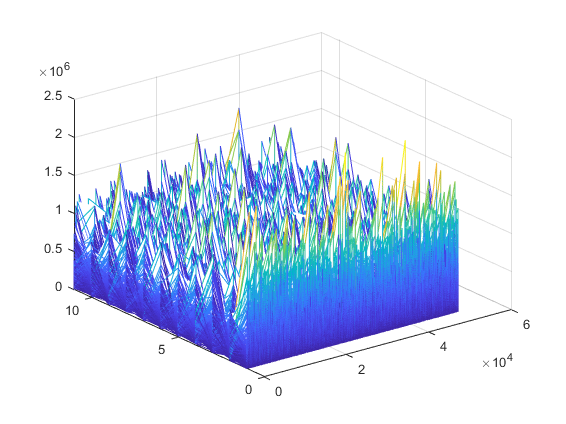

    24



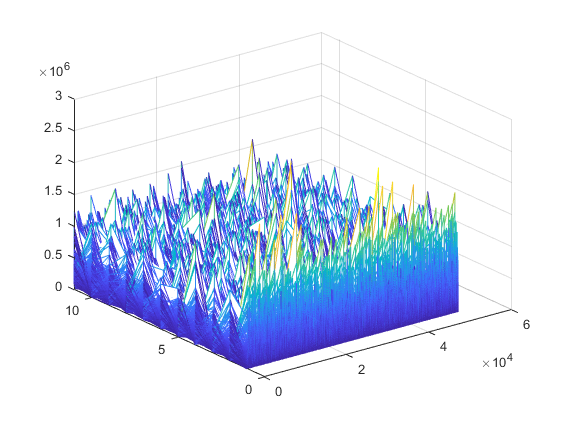

    25



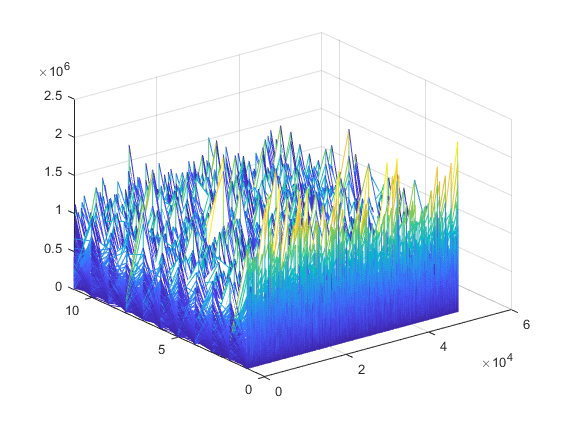

    26



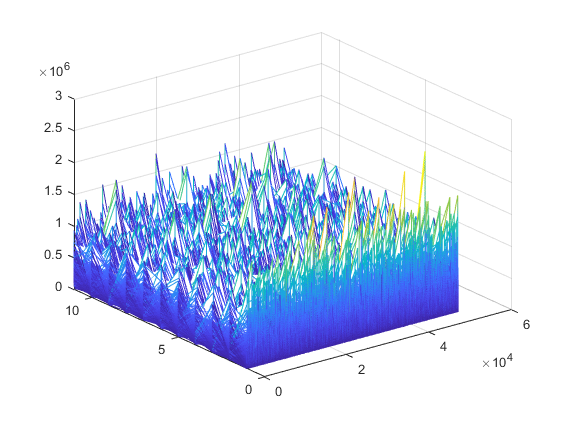

    27



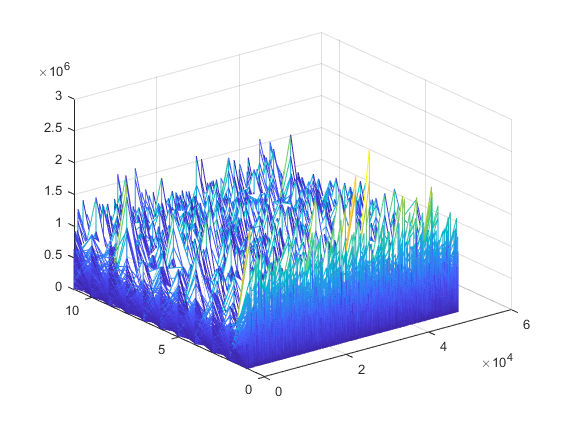

    28



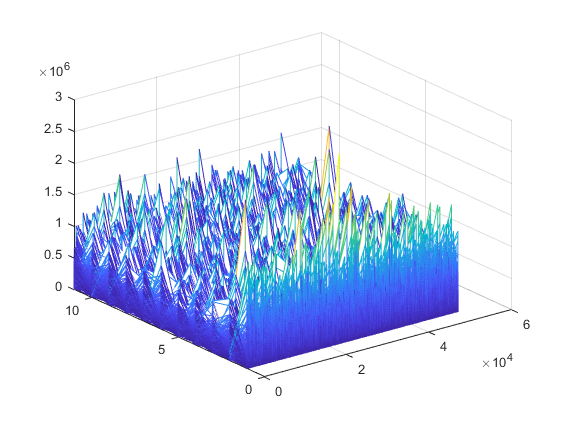

    29



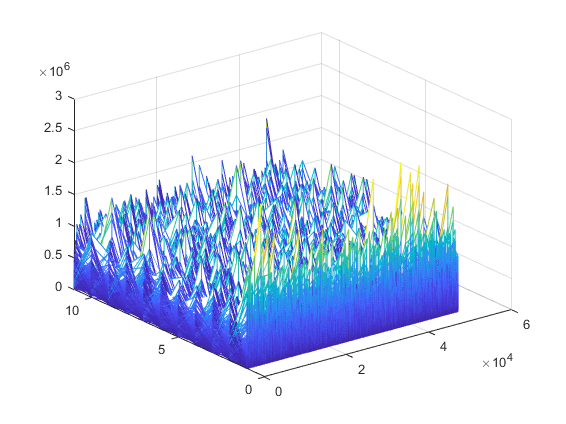

    30



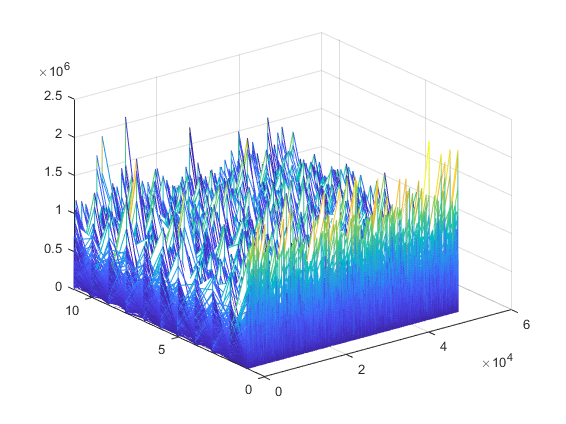

    31



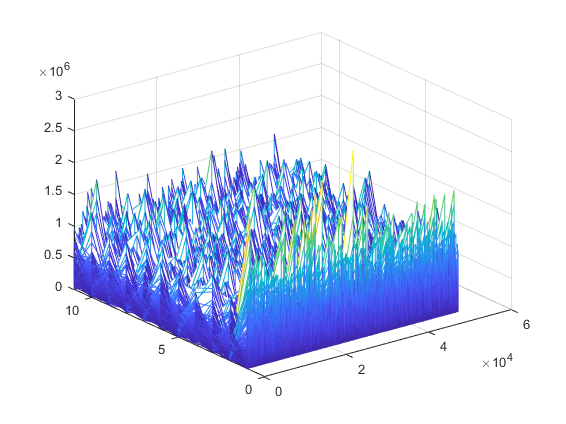

    32



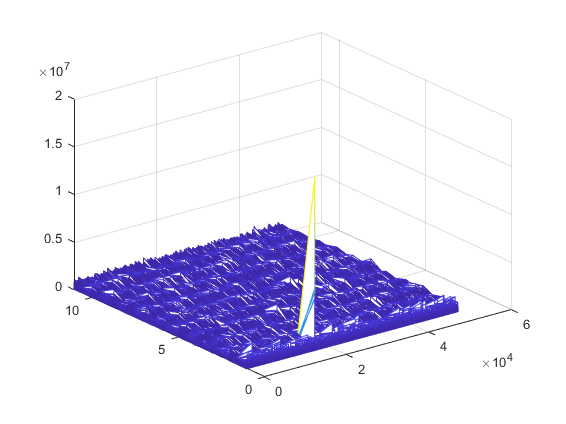

    33



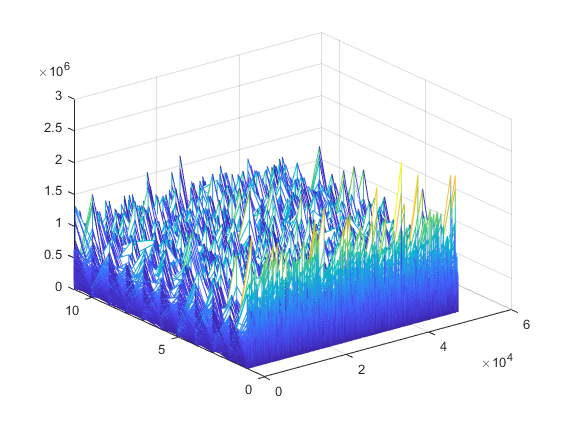

    34



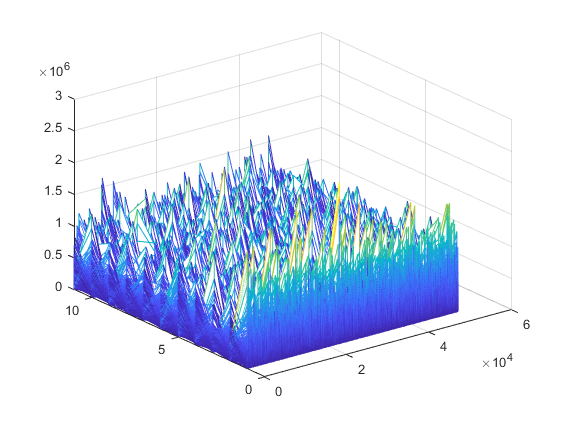

signal = signal(:, 2:2:length(signal));
t = Ts:Ts:time_chip;
signal = signal(:, 2:2:length(signal));
t = t(2:2:length(t));
i = 0;
for PRN = 20:34
    res = zeros(11, length(signal));
    B1C = weil_code_generator(10243, 10230, PRNList(PRN, 2), PRNList(PRN, 3));
    B1C = kron(B1C, ones(1, 5));
%     B1C = repmat(B1C, 1, 5);
    i = 0;
    for f = IF:freq_interval:IF + doppler_freq
        i = i + 1;
        cos_t = kron(cos(2 * pi * f * t), ones(N, 1));
        sin_t = kron(sin(2 * pi * f * t), ones(N, 1));
        signal_cos = signal .* cos_t;
        signal_sin = signal .* sin_t;
        
        signal_f = fft(signal_cos + 1i * signal_sin, [], 2);
        B1C_f = kron(conj(fft(B1C)), ones(N, 1));
        res(i, :) = sum(abs(ifft(signal_f .* B1C_f, [], 2)) .^ 2);
        
    end
    disp(PRN);
    figure;
    mesh(res(:, 1:length(signal)));
end